clear all; close all; clc;

J1 = 0.0025;         %kgm^2
J2 = 0.0018;         %kgm^2
J3 = 0.0018;         %kgm^2
k1 = 2.7;            %Nm/rad
k2 = 2.6;            %Nm/rad
b1 = 0.0029;         %Nms/rad
b2 = 0.0002;         %Nms/rad
b3 = 0.00015;        %Nms/rad
J_1 = J1;             %kgm^2
J_2 = J2;             %kgm^2
J_3 = J3;             %kgm^2
k_1 = k1;             %Nm/rad
k_2 = k2;             %Nm/rad
b_1 = b1;             %Nms/rad
b_2 = b2;             %Nms/rad
b_3 = b3;             %Nms/rad

A = [   0      1       0         0     0     0;
     -k1/J1 -b1/J1   k1/J1       0     0     0;
        0      0       0         1     0     0;
      k1/J2    0  -(k1+k2)/J2 -b2/J2 k2/J2   0;
        0      0       0         0     0     1;
        0      0     k2/J3       0  -k2/J3 -b3/J3];

B = [ 0  ;
     1/J1;
      0  ;
      0  ;
      0  ;
      0  ];

Ex = [  0  ;
      -1/J1;
        0  ;
        0  ;
        0  ;
        0  ];

C = [0 0 0 0 1 0];

D = zeros(1,1);

Ey = zeros(1,1);

%-------------------------------------------------Q9-------------------------------------------------------
s = tf('s');
% determining G and Gd from matrices
G = minreal(C*inv(s*eye(size(A,1)) - A)*B + D);
Gd = minreal(C*inv(s*eye(size(A,1)) - A)*Ex + Ey);

% low pass filter design
M = 2;
wb = 2.1; %2.1
A_ = 0.01;
WS = (s/M+wb)/(s+wb*A_);
WS = WS^3;

% high pass filter
M = 7;
wb = 7;
A_ = 0.07; %0.07
WKS = (s+wb/M)/(A_*s+wb);
WKS = WKS^2;

%for visualization min and max range of logspace
log_min = -2;
log_max = 3;

A = A;
B2 = B;
B1 = zeros(6,2);
C2 = -C;
C1 = [-WS*C; zeros(1,6)];
D11 = [WS -WS*Gd; 0 0];
D12 = [0; WKS];
D21 = [1 -Gd];
D22 = 0;

PA = [A B1 B2;
       C1 D11 D12;
       C2 D21 D22];

%Assumptions
if (rank(ctrb(A,B2))==size(A,1))
    disp("System is controllable -> stabilizable as well.")
end

System is controllable -> stabilizable as well.


if (rank(obsv(A,C2))==size(A,1))
    disp("System is observable -> detectable as well.")
end

System is observable -> detectable as well.



%just checked them
D12;
D21;
disp("D12 has full rank")

D12 has full rank


disp("D21 has full rank")

D21 has full rank



[A-s*eye(size(A)) B2; C1 D12];
[A-s*eye(size(A)) B1; C2 D21];

D11;
D22;

P = [ WS -WS*Gd -WS*G ;
      0     0    WKS  ;
      1    -Gd   -G   ];

%controller design
[K_inf, CL, Gam, ~] = mixsyn(G, WS, WKS, []);
Gam

Gam = 0.8740

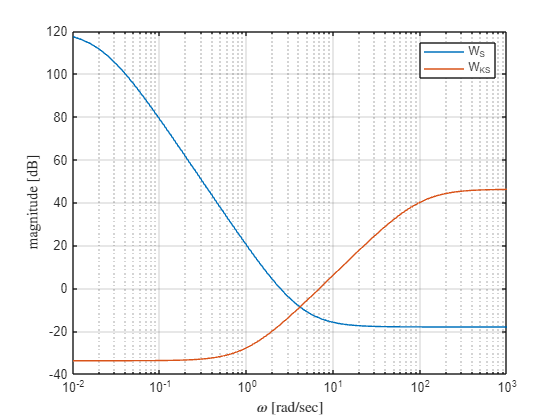

%We want to stray away from the optimal solutino
[K_inf, CL, Gam, ~] = mixsyn(G, WS, WKS, [], [Gam*1.02 Gam*1.02]);

% S, SK and T
S = 1/(1+K_inf*G);
SK = S*K_inf;
T = K_inf*G*S;


[mag, phase, omega] = bode(WS, logspace(log_min, log_max, 50));
mag_Ws = squeeze(mag);
omega_Ws = squeeze(omega);

[mag, phase, omega] = bode(WKS, logspace(log_min, log_max, 50));
mag_W_ks = squeeze(mag);
omega_W_ks = squeeze(omega);

% Two weight functions applied to S and SK
figure(1)
semilogx(omega_Ws, 20*log10(mag_Ws)); hold on;
semilogx(omega_W_ks, 20*log10(mag_W_ks)); hold off;
legend({"W_S", "W_{KS}"});
ylabel("magnitude [dB]", Interpreter="latex");
xlabel("$\omega$ [rad/sec]", Interpreter="latex");
grid on;

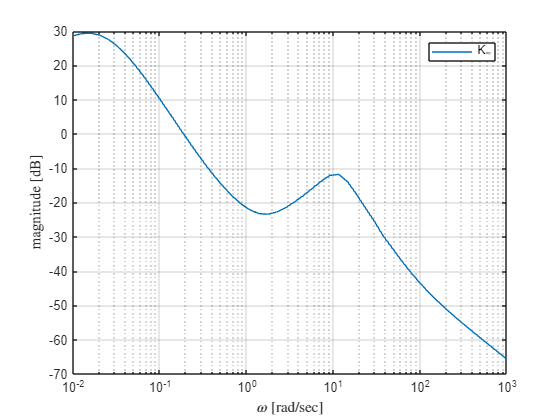

clf;

[mag, phase, omega] = bode(K_inf, logspace(log_min, log_max, 50));
mag = squeeze(mag);  % Convert magnitude matrix to a vector
omega = squeeze(omega);  % Convert omega matrix to a vector

% Controller bode (high gain at low frequencies)
figure(2);
semilogx(omega, 20*log10(mag)); %hold on;
% plot([1 1], [min(20*log10(mag)) max(20*log10(mag))], 'r', 'LineWidth', 2); hold on;
% plot([min(omega) max(omega)], [0 0], 'b', 'LineWidth', 2); hold off;
legend({"K_{\infty}"});
ylabel("magnitude [dB]", Interpreter="latex");
xlabel("$\omega$ [rad/sec]", Interpreter="latex");
grid on;

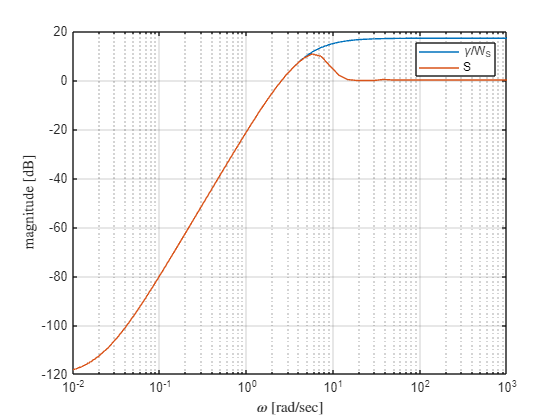

clf;


[mag, phase, omega] = bode(Gam/WS, logspace(log_min, log_max, 50));
mag_gpWs = squeeze(mag);
omega_gpWs = squeeze(omega);

[mag, phase, omega] = bode(S, logspace(log_min, log_max, 50));
mag_S = squeeze(mag);
omega_S = squeeze(omega);

%Sensitivity function is always below gamma/WS
figure(3);
semilogx(omega_gpWs, 20*log10(mag_gpWs)); hold on;
semilogx(omega_S, 20*log10(mag_S)); hold off;
legend({"\gamma/W_S", "S"});
ylabel("magnitude [dB]", Interpreter="latex");
xlabel("$\omega$ [rad/sec]", Interpreter="latex");
grid on;

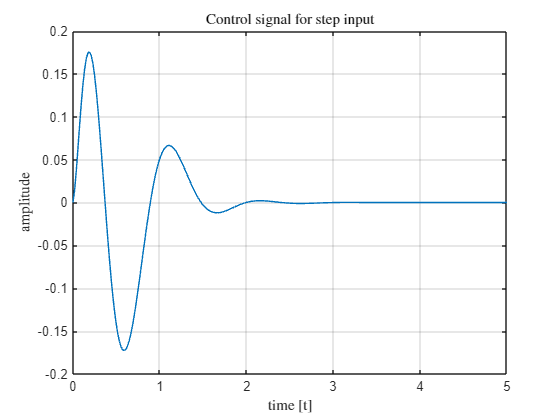

clf;

[stp, t] = step(SK, 5);

% Contorl signal
figure(4);
plot(t, stp);
title("Control signal for step input", Interpreter="latex");
xlabel("time [t]", Interpreter="latex");
ylabel("amplitude", Interpreter="latex");
grid on;

clf;

% Gamma is below 1 and not optimal
Gam

Gam = 0.8909

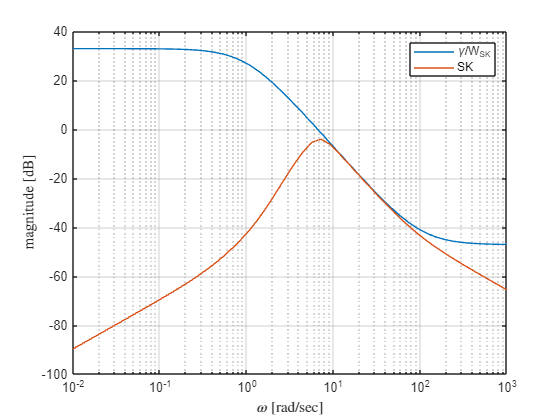




[mag, phase, omega] = bode(Gam/WKS, logspace(log_min, log_max, 50));
mag_gpWks = squeeze(mag);
omega_gpWks = squeeze(omega);

[mag, phase, omega] = bode(SK, logspace(log_min, log_max, 50));
mag_Sk = squeeze(mag);
omega_Sk = squeeze(omega);

% KS is always below Gam/WKS
figure(5);
semilogx(omega_gpWks, 20*log10(mag_gpWks)); hold on;
semilogx(omega_Sk, 20*log10(mag_Sk)); hold off;
legend({"\gamma/W_{SK}", "SK"});
ylabel("magnitude [dB]", Interpreter="latex");
xlabel("$\omega$ [rad/sec]", Interpreter="latex");
grid on;

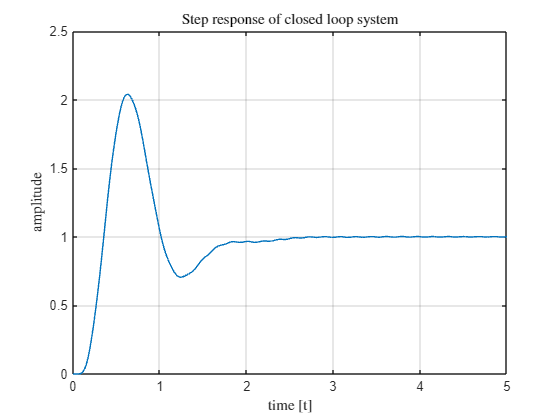

clf;

[stp, t] = step(T, 5);

% step response (response time shall be under 2 sec)
figure(6);
plot(t, stp);
title("Step response of closed loop system", Interpreter="latex");
xlabel("time [t]", Interpreter="latex");
ylabel("amplitude", Interpreter="latex");
grid on;

clf;

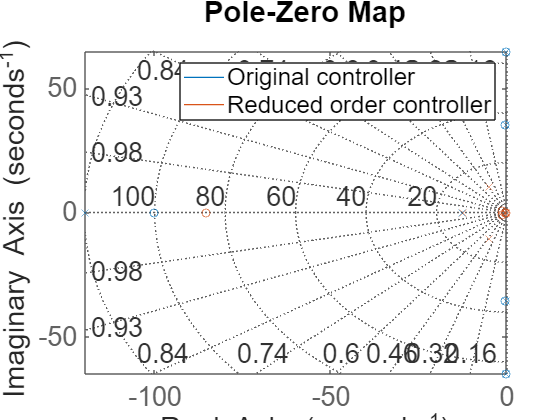

%-------------------------------------------------Q10------------------------------------------------------
K_red_2 = getrom(reducespec(K_inf, 'balanced'), Order=6);
Kred = reduce(K_inf, 6);
%manual DK iteration??

%pole-zero map of the two controllers
figure(7);
pzmap(K_inf); hold on;
pzmap(Kred); hold off;
legend({"Original controller", "Reduced order controller"});
grid on;

clf;

%Stability analysis
S_red = 1/(1+Kred*G);
SK_red = S_red*Kred;
T_red = Kred*G*S_red;

if (all(real(pole(T_red)) < 0))
    disp("Closed loop is stable because all poles are on the LHT")
end

Closed loop is stable because all poles are on the LHT


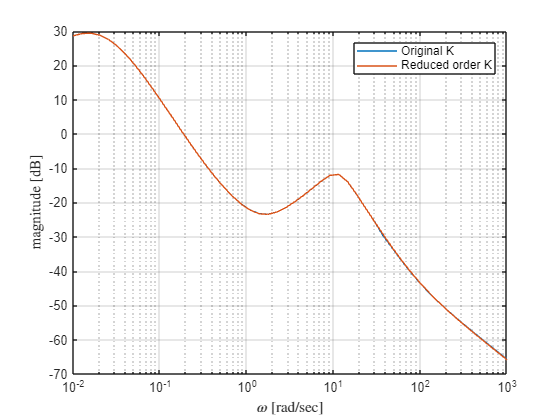


[mag, phase, omega] = bode(K_inf, logspace(log_min, log_max, 50));
mag_Kinf = squeeze(mag);
omega_Kinf = squeeze(omega);

[mag, phase, omega] = bode(Kred, logspace(log_min, log_max, 50));
mag_Kred = squeeze(mag);
omega_Kred = squeeze(omega);

%difference between the two controllers
figure(9);
semilogx(omega_Kinf, 20*log10(mag_Kinf)); hold on;
semilogx(omega_Kred, 20*log10(mag_Kred)); hold off;
legend({"Original K", "Reduced order K"});
ylabel("magnitude [dB]", Interpreter="latex");
xlabel("$\omega$ [rad/sec]", Interpreter="latex");
grid on;

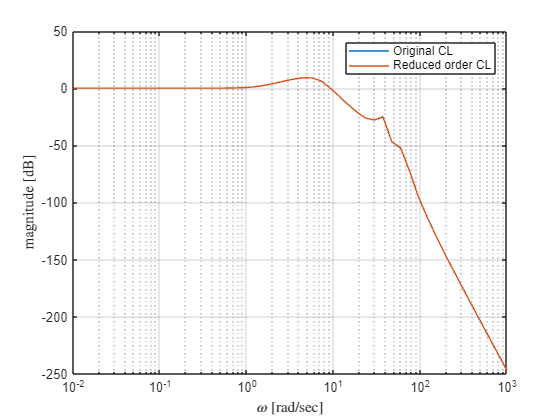

clf;

[mag, phase, omega] = bode(T, logspace(log_min, log_max, 50));
mag_t = squeeze(mag);
omega_t = squeeze(omega);

[mag, phase, omega] = bode(T_red, logspace(log_min, log_max, 50));
mag_tred = squeeze(mag);
omega_tred = squeeze(omega);

%difference between the two controllers
figure(14);
semilogx(omega_t, 20*log10(mag_t)); hold on;
semilogx(omega_tred, 20*log10(mag_tred)); hold off;
legend({"Original CL", "Reduced order CL"});
ylabel("magnitude [dB]", Interpreter="latex");
xlabel("$\omega$ [rad/sec]", Interpreter="latex");
grid on;

clf;

%-------------------------------------------------Q11------------------------------------------------------
[K_2, CL, Gam_2, ~] = mixsyn(G, WS, WKS, [], [Inf, Inf]);
Gam_2

Gam_2 = 1.4779

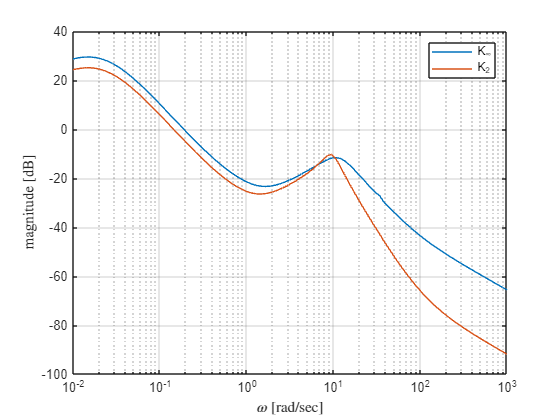


S_2 = 1/(1+K_2*G);
SK_2 = S_2*K_2;
T_2 = K_2*G*S_2;

[mag, phase, omega] = bode(K_inf, logspace(log_min, log_max, 100));
mag_K_inf = squeeze(mag);
omega_K_inf = squeeze(omega);

[mag, phase, omega] = bode(K_2, logspace(log_min, log_max, 100));
mag_K_2 = squeeze(mag);
omega_K_2 = squeeze(omega);

%H_inf and H_2 controller
figure(10);
semilogx(omega_K_inf, 20*log10(mag_K_inf)); hold on;
semilogx(omega_K_2, 20*log10(mag_K_2)); hold off;
legend({"K_{\infty}", "K_{2}"});
ylabel("magnitude [dB]", Interpreter="latex");
xlabel("$\omega$ [rad/sec]", Interpreter="latex");
grid on;

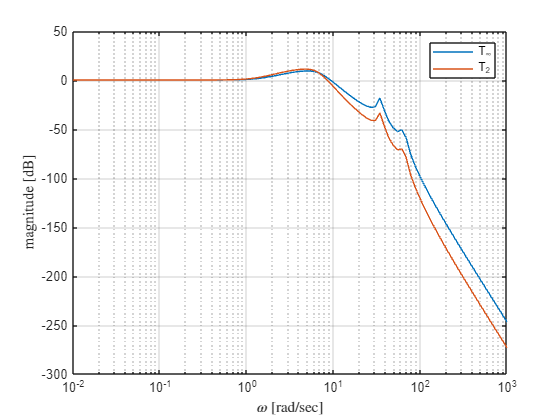

clf;

[mag, phase, omega] = bode(T, logspace(log_min, log_max, 100));
mag_T = squeeze(mag);
omega_T = squeeze(omega);

[mag, phase, omega] = bode(T_2, logspace(log_min, log_max, 100));
mag_T_2 = squeeze(mag);
omega_T_2 = squeeze(omega);

%T and T_2 closed loop tfs
figure(11);
semilogx(omega_T, 20*log10(mag_T)); hold on;
semilogx(omega_T_2, 20*log10(mag_T_2)); hold off;
legend({"T_{\infty}", "T_{2}"});
ylabel("magnitude [dB]", Interpreter="latex");
xlabel("$\omega$ [rad/sec]", Interpreter="latex");
grid on;

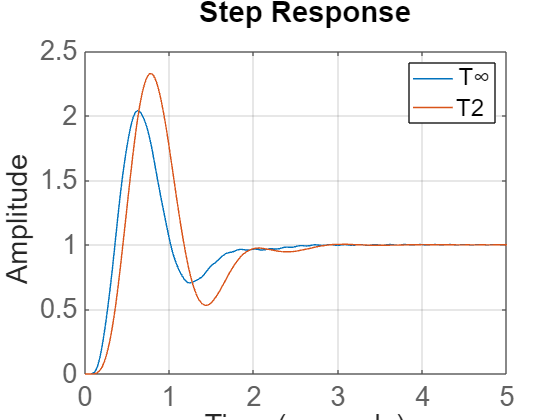

clf;

%+ step function
figure(12);
step(T, 5); hold on;
step(T_2, 5); hold off;
legend({"T{\infty}", "T2"});
grid on;

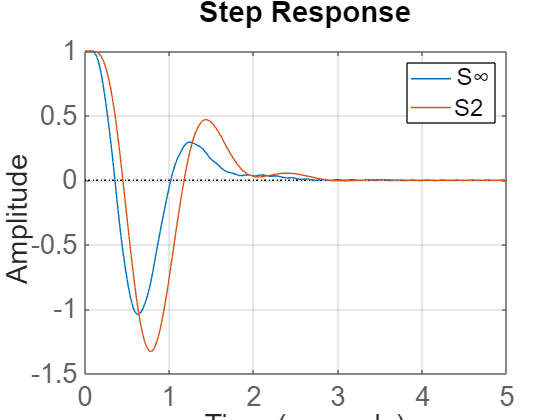

clf;

%+ control input
figure(12);
step(S, 5); hold on;
step(S_2, 5); hold off;
legend({"S{\infty}", "S2"});
grid on;

clf;

%-------------------------------------------------Q12------------------------------------------------------
load("ECP502Data.mat")
load("ECP_values.mat")

T_s = 0.004;
simTime = 10;
SIM_TIME = simTime;
STEP_SIZE = T_s;
atan_scale = 100;
w_th = 0.75;
T_Cp = ECP_values(12);
T_Cm = ECP_values(13);
x_0 = zeros(1,6);
B_change = [1 0;0 0];
sigma1 = 0.0093; %one noise is necessary since we measure only dis 3's position

Kred_tf = tf(Kred);
Kred_tf_d = c2d(Kred_tf,T_s);

sim("threeDiskOscillatorRig.slx");

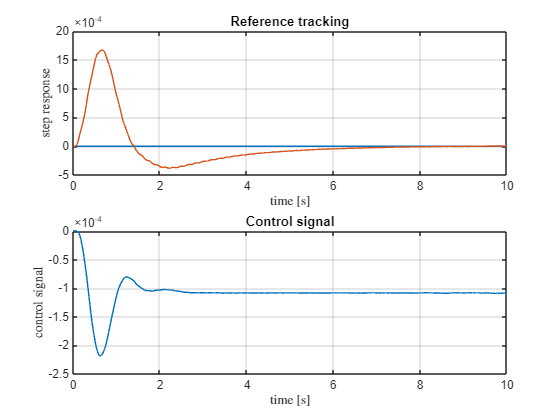


t = u_sim.Time;
ref_sim = ref_sim.Data;
u_sim = u_sim.Data;
y_sim = y_sim.Data;

figure(13);
subplot(2,1,1);
plot(t, ref_sim); hold on;
plot(t, y_sim); hold off;
title("Reference tracking");
xlabel("time [s]", Interpreter='latex');
ylabel("step response", Interpreter='latex');
grid on;
subplot(2,1,2);
plot(t, u_sim);
title("Control signal");
xlabel("time [s]", Interpreter='latex');
ylabel("control signal", Interpreter='latex');
grid on;

clf;

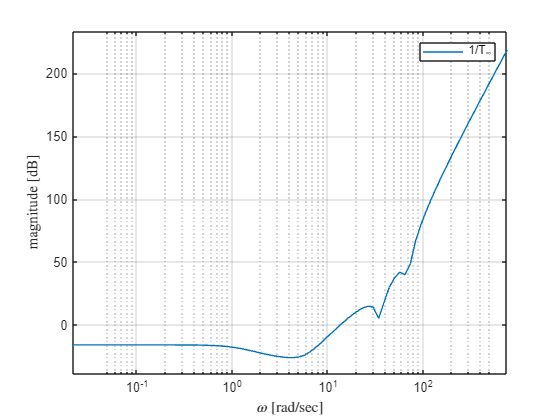

%-------------------------------------------------Q13------------------------------------------------------

[mag, phase, omega] = bode(1/T_red, logspace(log_min, log_max, 100));
mag_1pT_red = squeeze(mag);
omega_1pT_red = squeeze(omega);

%T and T_2 closed loop tfs
figure(14);
semilogx(omega_1pT_red, 20*log10(mag_1pT_red));
legend({"1/T_{\infty}"});
ylabel("magnitude [dB]", Interpreter="latex");
xlabel("$\omega$ [rad/sec]", Interpreter="latex");
grid on;

clf;


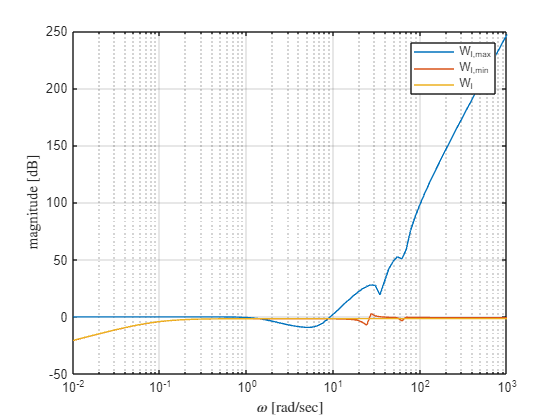

%-------------------------------------------------Q14------------------------------------------------------
J1 = 0.0325;         %kgm^2
J_1 = J1;            %kgm^2

A = [   0      1       0         0     0     0;
     -k1/J1 -b1/J1   k1/J1       0     0     0;
        0      0       0         1     0     0;
      k1/J2    0  -(k1+k2)/J2 -b2/J2 k2/J2   0;
        0      0       0         0     0     1;
        0      0     k2/J3       0  -k2/J3 -b3/J3];

B = [ 0  ;
     1/J1;
      0  ;
      0  ;
      0  ;
      0  ];

Ex = [  0  ;
      -1/J1;
        0  ;
        0  ;
        0  ;
        0  ];

C = [0 0 0 0 1 0];

D = zeros(1,1);

Ey = zeros(1,1);

W_not_supposed_to_be_here = tf([0.833 0], [1 0.089]);

%Q14
G_14 = minreal(C*inv(s*eye(size(A,1)) - A)*B + D);
Gd_14 = minreal(C*inv(s*eye(size(A,1)) - A)*Ex + Ey);

[mag, phase, omega] = bode(G_14/G-1, logspace(log_min, log_max, 100));
mag_WI_min = squeeze(mag);
omega_WI_min = squeeze(omega);

[mag, phase, omega] = bode(W_not_supposed_to_be_here, logspace(log_min, log_max, 100));
mag_W_not_supposed_to_be_here = squeeze(mag);
omega_W_not_supposed_to_be_here = squeeze(omega);

%T and T_2 closed loop tfs
figure(15);
semilogx(omega_1pT_red, 20*log10(mag_1pT_red)); hold on;
semilogx(omega_WI_min, 20*log10(mag_WI_min)); hold on;
semilogx(omega_W_not_supposed_to_be_here, 20*log10(mag_W_not_supposed_to_be_here)); hold off;
legend({"W_{I,max}", "W_{I,min}", "W_{I}"});
ylabel("magnitude [dB]", Interpreter="latex");
xlabel("$\omega$ [rad/sec]", Interpreter="latex");
grid on;

I am not sure about these wight functions as they cross each other at around 1.3 rad/sec that implies controller can be designed up to that frequency.....

%-------------------------------------------------Q15------------------------------------------------------
%NEED TO TUNE THE WEIGHTS


% low pass filter design
M = 3;
wb = 1.1; %2.1
A_ = 0.01;
WS = (s/M+wb)/(s+wb*A_);
WS = WS^3;

% high pass filter
M = 7;
wb = 3;
A_ = 0.07; %0.07
WKS = (s+wb/M)/(A_*s+wb);
%WKS = WKS^2;

%provided weight function
WT = tf([0.833 0], [1 0.089]);

[K_inf, CL, Gam, ~] = mixsyn(G_14, WS, WKS, WT);
[K_inf, CL, Gam, ~] = mixsyn(G_14, WS, WKS, WT, [Gam*1.02 Gam*1.02]);
Gam

Gam = 1.4170

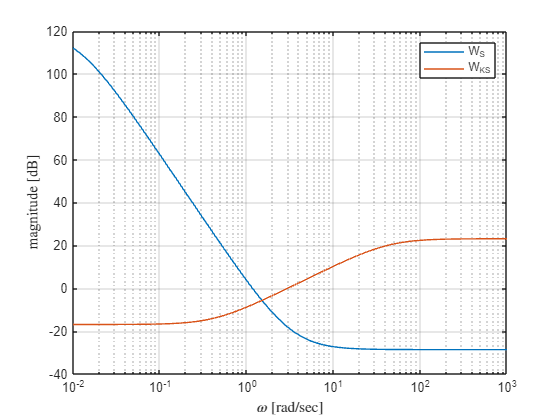


% S, SK and T
S = 1/(1+K_inf*G_14);
SK = S*K_inf;
T = K_inf*G_14*S;

[mag, phase, omega] = bode(WS, logspace(log_min, log_max, 50));
mag_Ws = squeeze(mag);
omega_Ws = squeeze(omega);

[mag, phase, omega] = bode(WKS, logspace(log_min, log_max, 50));
mag_W_ks = squeeze(mag);
omega_W_ks = squeeze(omega);

% Two weight functions applied to S and SK
figure(16)
semilogx(omega_Ws, 20*log10(mag_Ws)); hold on;
semilogx(omega_W_ks, 20*log10(mag_W_ks)); hold off;
legend({"W_S", "W_{KS}"});
ylabel("magnitude [dB]", Interpreter="latex");
xlabel("$\omega$ [rad/sec]", Interpreter="latex");
grid on;

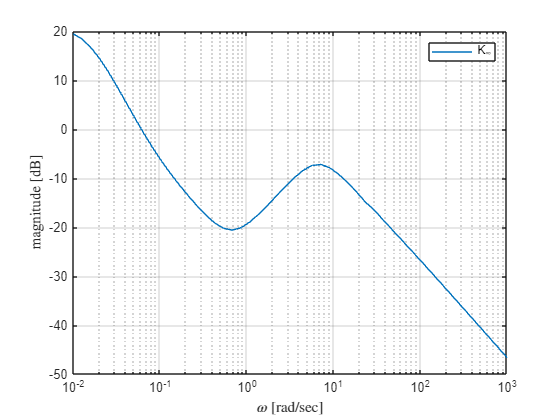

clf;

[mag, phase, omega] = bode(K_inf, logspace(log_min, log_max, 50));
mag = squeeze(mag);  % Convert magnitude matrix to a vector
omega = squeeze(omega);  % Convert omega matrix to a vector

% Controller bode (high gain at low frequencies)
figure(17);
semilogx(omega, 20*log10(mag)); %hold on;
% plot([1 1], [min(20*log10(mag)) max(20*log10(mag))], 'r', 'LineWidth', 2); hold on;
% plot([min(omega) max(omega)], [0 0], 'b', 'LineWidth', 2); hold off;
legend({"K_{\infty}"});
ylabel("magnitude [dB]", Interpreter="latex");
xlabel("$\omega$ [rad/sec]", Interpreter="latex");
grid on;

clf;